# Cosas Previas TFG

En este archivo Live de Matlab pretendo agrupar en un solo sitio el trabajo preliminar de la preparacion de las diferentes matrices que se van a emplear durante el trabajo. Cada una separada en un chunk diferente para mejor legibilidad.

clear all 
clc
clf

addpath('D:\## DOCUMENTOS ##\UCM\TFG')
datos_brutos = importdata('france_and_spain_germany_italy_portugal.tex_colabora_links.txt',' ');

## Tratamientos del documento de datos_brutos para el calculo de distintas cantidades

h1 = max(datos_brutos(:,1)), h2 = max(datos_brutos(:,2));

h1 = 9087

h = max([h1 h2]);
datos_brutos_unique = unique(datos_brutos,'rows'); %Esta instruccion para lo sin pesos agiliza todo bastante
% En la tercera columna los valores de cada pais son los siguientes:
%      1 == Francia
%      2 == España
%      3 == Alemania
%      4 == Italia
%      5 == Portugal
%      100 == Colaboracion Internacional

autores1 = [];
autores2 = [];
autores3 = [];
autores4 = [];
autores5 = [];
autores100 = []; % Autores que hacen al menos una colaboracion internacional.
% Calculamos los valores de las variables autores definidas:
for i = 1:size(datos_brutos,1)
    if datos_brutos(i,3) == 1
        if ismember(datos_brutos(i,1),autores1)==false %Si no esta el 1-er autor de la fila i se añade.
            autores1 = [autores1; datos_brutos(i,1)];
        end
        if ismember(datos_brutos(i,2),autores1)==false %Si no esta el 2º autor de la fila i se añade.
            autores1 = [autores1; datos_brutos(i,2)];
        end
    elseif datos_brutos(i,3) == 2
        if ismember(datos_brutos(i,1),autores2)==false %Si no esta el 1-er autor de la fila i se añade.
            autores2 = [autores2; datos_brutos(i,1)];
        end
        if ismember(datos_brutos(i,2),autores2)==false %Si no esta el 2º autor de la fila i se añade.
            autores2 = [autores2; datos_brutos(i,2)];
        end
    elseif datos_brutos(i,3) == 3
        if ismember(datos_brutos(i,1),autores3)==false %Si no esta el 1-er autor de la fila i se añade.
            autores3 = [autores3; datos_brutos(i,1)];
        end
        if ismember(datos_brutos(i,2),autores3)==false %Si no esta el 2º autor de la fila i se añade.
            autores3 = [autores3; datos_brutos(i,2)];
        end
    elseif datos_brutos(i,3) == 4
        if ismember(datos_brutos(i,1),autores4)==false %Si no esta el 1-er autor de la fila i se añade.
            autores4 = [autores4; datos_brutos(i,1)];
        end
        if ismember(datos_brutos(i,2),autores4)==false %Si no esta el 2º autor de la fila i se añade.
            autores4 = [autores4; datos_brutos(i,2)];
        end
    elseif datos_brutos(i,3) == 5
        if ismember(datos_brutos(i,1),autores5)==false %Si no esta el 1-er autor de la fila i se añade.
            autores5 = [autores5; datos_brutos(i,1)];
        end
        if ismember(datos_brutos(i,2),autores5)==false %Si no esta el 2º autor de la fila i se añade.
            autores5 = [autores5; datos_brutos(i,2)];
        end
    elseif datos_brutos(i,3) == 100
        if ismember(datos_brutos(i,1),autores100)==false %Si no esta el 1-er autor de la fila i se añade.
            autores100 = [autores100; datos_brutos(i,1)];
        end
        if ismember(datos_brutos(i,2),autores100)==false %Si no esta el 2º autor de la fila i se añade.
            autores100 = [autores100; datos_brutos(i,2)];
        end
    end
end
% /// 1. Contamos si de los h=9088 autores realmente aparecen los 9088.
missing_contador_autores= 0;
missing_array_autores = [];
for i=1:h
    if ismember(i,datos_brutos)  
        % Todo bien, pasamos al siguiente i.
        % Como en la tercera columna los valores posibles son 1,2,3,4,5,100 ya he comprobado a mano que esos 
        % autores (el autor de indice 1,etc...) sí estan en las 2 primeras columnas de datos_brutos
        % ergo no hay errores en esta instruccion.
    else
       missing_array_autores = [missing_array_autores i];
       missing_contador_autores = missing_contador_autores+1;
       %fprintf('El valor autor %d no esta entre los autores\n', i); %Si queremos que se muestre por pantalla.
    end
end

% /// 2. Comprobacion de que los autores internacionales NO SOLO son internacionales.
varaux_de_control=0;
for i=1:length(autores100)
    if ((ismember(autores100(i),autores1))||(ismember(autores100(i),autores2))||(ismember(autores100(i),autores3))||...
            (ismember(autores100(i),autores4))||(ismember(autores100(i),autores5)))
        varaux_de_control = varaux_de_control+1;
    else
        fprintf('El valor en la posición %d, autor %d SOLO ES INTERNACIONAL\n', i, autores100(i));
    end
end
if varaux_de_control==length(autores100)
    disp("Ningun autor solo internacional")
end

Ningun autor solo internacional


## Creacion de las Matrices:

- ***Colab***: Matriz de adyacencia que tiene valor 1 en (i,j) si el autor i ha colaborado con el autor j. La diagonal es 0.

- ***Colab_diag***: Es la matriz Colab pero sin eliminar la diagonal, es decir, cuanta las colaboraciones que ahce un autor consigo mismo (Hay 2 autores que colaboran con ellos mismos)(No hay pesos)(Es la unica matriz que tiene diagonal).

- ***Colab_A***: Colab restringida a los autores de ALEMANIA.

- ***Colab_F***: Colab restringida a los autores de FRANCIA.

- ***Colab_E***: Colab restringida a los autores de ESPAÑA.

- ***Colab_I***: Colab restringida a los autores de ITALIA.

- ***Colab_P***: Colab restringida a los autores de PORTUGAL.

- ***Colab_XY***: Colab restringida a los autores de los paises X e Y (SE HARA CUANDO SE NECESITE EMPLEARLA)    .

#### Explicacion sobre las dimensiones obtenidas de las matrices:

La idea preconcebida es que la dimension de Colab_E sea (Nº autores españoles)x(Nº autores españoles) pero como el indice del autor determina el numero de la fila si el autor 3259 es español se creara un valor 1 el la fila 3259 de la matriz Colab_E pese a tener España solo 1489 autores. Debido a esto, por el momento creo todas las matrices de tamaño 9088x9088 con valores no nulos donde esten las colaboraciond de los autores españoles. Será como extraer el el bloque de españoles de la matriz global Colab.

Mas adelante cojo estas matrices y las "cerco" para que tengan dimension igual a (Nº autores del país)x(Nº autores del país)

Colab = zeros(h);
Colab_diag = zeros(h);
Colab_F = zeros(h);
Colab_E = zeros(h);
Colab_A = zeros(h);
Colab_I = zeros(h);
Colab_P = zeros(h);

% Sin pesos
for i = 1:size(datos_brutos_unique,1)
    auxA = datos_brutos_unique(i,1:3);%Variable auxiliar para el bucle
    Colab_diag(auxA(1),auxA(2)) = 1;
    Colab_diag(auxA(2),auxA(1)) = 1; 
    if auxA(1)~=auxA(2)
        Colab(auxA(1),auxA(2)) = 1;
        Colab(auxA(2),auxA(1)) = 1;
        switch auxA(3)
            case 1 %Francia
                Colab_F(auxA(1),auxA(2)) = 1;
                Colab_F(auxA(2),auxA(1)) = 1;
            case 2 %España
                Colab_E(auxA(1),auxA(2)) = 1;
                Colab_E(auxA(2),auxA(1)) = 1;         
            case 3 %Alemania
                Colab_A(auxA(1),auxA(2)) = 1;
                Colab_A(auxA(2),auxA(1)) = 1;
            case 4 %Italia
                Colab_I(auxA(1),auxA(2)) = 1;
                Colab_I(auxA(2),auxA(1)) = 1;
            case 5 %Portugal
                Colab_P(auxA(1),auxA(2)) = 1;
                Colab_P(auxA(2),auxA(1)) = 1;
        end
    end 
end

#### **Guardamos las matrices en un .txt **

writematrix(Colab,'Colab','Delimiter',' ')
writematrix(Colab_diag,'Colab_diag','Delimiter',' ')
writematrix(Colab_F,'Colab_F','Delimiter',' ')
writematrix(Colab_E,'Colab_E','Delimiter',' ')
writematrix(Colab_A,'Colab_A','Delimiter',' ')
writematrix(Colab_I,'Colab_I','Delimiter',' ')
writematrix(Colab_P,'Colab_P','Delimiter',' ')

#### Pasamos a Sparse Matrix

El sufijo ***_S*** determina que esa matriz es una Sparse Matrix

Colab_S = sparse(Colab);
%whos Colab_S %SUMMARY BREVE
Colab_diag_S = sparse(Colab_diag);
Colab_F_S = sparse(Colab_F);
Colab_E_S = sparse(Colab_E);
Colab_A_S = sparse(Colab_A);
Colab_I_S = sparse(Colab_I);
Colab_P_S = sparse(Colab_P);

## **Calculos y comprobaciones POST creacion de las matrices:**

disp("Numero de autores que trabajan con ellos mismos\n")

Numero de autores que trabajan con ellos mismos\n


sum(diag(Colab_diag)) % Solo hay 2 autores que trabajan con ellos mismos

ans = 2

#### Maximo indice del autor de cada país (Final de cada bloque):

max_pais = zeros(1,5);
for i = 1:size(datos_brutos_unique,1)
    if datos_brutos_unique(i,3) == 1
        if datos_brutos_unique(i,2)>max_pais(1)
            max_pais(1)=datos_brutos_unique(i,2);
        end
    elseif datos_brutos_unique(i,3) == 2
        if datos_brutos_unique(i,2)>max_pais(2)
            max_pais(2)=datos_brutos_unique(i,2);
        end
    elseif datos_brutos_unique(i,3) == 3
        if datos_brutos_unique(i,2)>max_pais(3)
            max_pais(3)=datos_brutos_unique(i,2);
        end
    elseif datos_brutos_unique(i,3) == 4
        if datos_brutos_unique(i,2)>max_pais(4)
            max_pais(4)=datos_brutos_unique(i,2);
        end
    elseif datos_brutos_unique(i,3) == 5
        if datos_brutos_unique(i,2)>max_pais(5)
            max_pais(5)=datos_brutos_unique(i,2);
        end
    end
end
max_pais

max_pais =         1920        3413        6248        8841        9088


## REPRESENTACIONES GRAFICAS 

A continuacion algunas representaciones graficas de las matrices sparse anteriores:

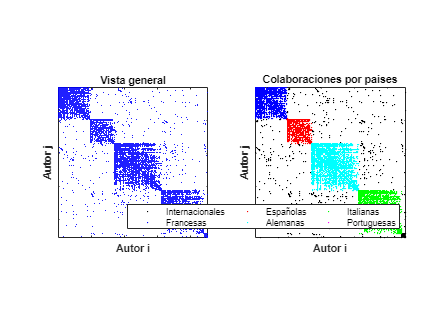

clf

subplot(1,2,1)
spy(Colab_S,'b.',1) 
xticklabels(' ')
yticklabels(' ')
title('Vista general')
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')

subplot(1,2,2)
spy(Colab_S,'k')
xticklabels(' ')
yticklabels(' ')
hold on
spy(Colab_F_S,'b')
spy(Colab_E_S,'r')
spy(Colab_A_S,'c')
spy(Colab_I_S,'g')
spy(Colab_P_S,'m')
legend({'Internacionales','Francesas','Españolas','Alemanas','Italianas','Portuguesas'},...
    'Location','southeast','NumColumns',3)
title('Colaboraciones por paises')
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')
hold off %Nota: Esta ultima grafica solo pone el nz de los portugueses

#### Grafica de la red como grafo

Observese la creacion de numerosas mini islas ya que el grafo no es conexo y matalb lo organiza como conisdera mejor.

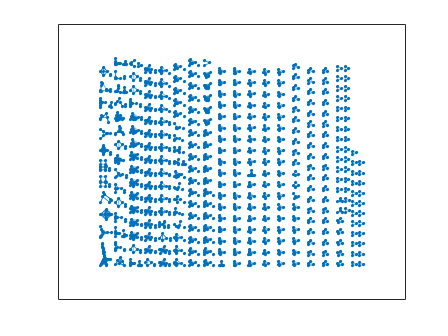

clf
G = graph(Colab_S);
G_edges = G.Edges; %Las aristas
plot(G)

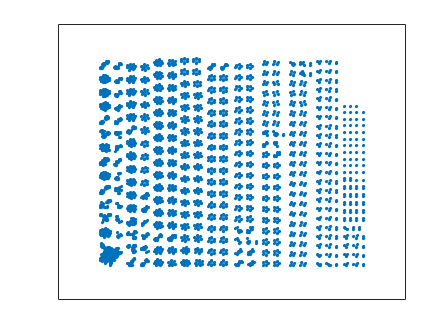

plot(G, 'Layout', 'force')

plot(G, 'Layout', 'subspace')

Como lo anterior es rematadamente feo pruebo a hacerlo mas pequeño, solo el grafo de los portugueses

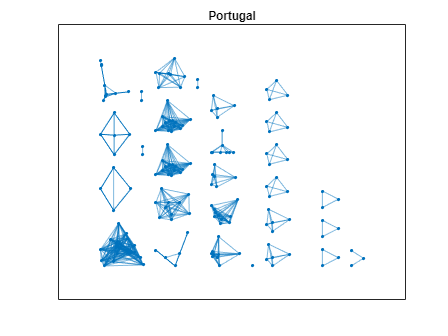

G2 = graph(Colab_S(8842:9088,8842:9088));
plot(G2)
title('Portugal')

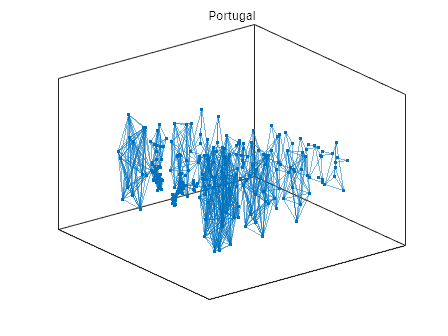

plot(G2, 'Layout', 'force3')
title('Portugal')

Concluyo que la representacion es correcta pero como hay grados tan dispares y tantos nodos la representacion los agrupa en mini mini clusters para que sea visible. Si interactuamos con el gráfico observamos que hay puntos que solo se unen entre ellos ya que ambso tienen grado 1. La grafica no representa su pais ni nada, ya que coloca los nodos como mejor considera sin tener en cuenta el orden numerico.

## Creacion de la Super Matrix Colaboraciones ORDENADA  *SM_Colab*

Gracias a los tamaños de autores1,2,3,4 y 5 y del tamaño de los bloques de cada pais en las representaciones graficas anteriores vamos ahora a crear la super matrix ordenada de mayor bloques a menor bloques para una mejor representacion visual.

Fra_Colab = Colab_S(1:max_pais(1),1:max_pais(1));
Esp_Colab = Colab_S(max_pais(1)+1:max_pais(2),max_pais(1)+1:max_pais(2));
Ale_Colab = Colab_S(max_pais(2)+1:max_pais(3),max_pais(2)+1:max_pais(3));
Ita_Colab = Colab_S(max_pais(3)+1:max_pais(4),max_pais(3)+1:max_pais(4));
Por_Colab = Colab_S(max_pais(4)+1:max_pais(5),max_pais(4)+1:max_pais(5));
SM_Colab = blkdiag(Ale_Colab,Ita_Colab,Fra_Colab,Esp_Colab,Por_Colab);

Graficamos matrices

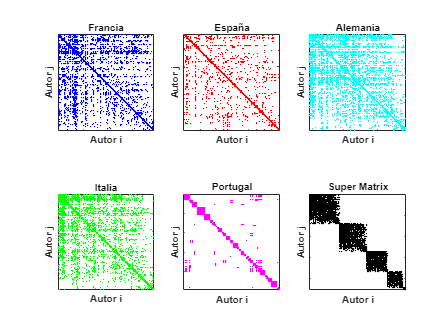

subplot(2,3,1)
spy(Fra_Colab,'b')
title('Francia')
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')
xticklabels(' ')
yticklabels(' ')
subplot(2,3,2)
spy(Esp_Colab,'r')
title('España')
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')
xticklabels(' ')
yticklabels(' ')
subplot(2,3,3)
spy(Ale_Colab,'c')
title('Alemania')
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')
xticklabels(' ')
yticklabels(' ')
subplot(2,3,4)
spy(Ita_Colab,'g')
title('Italia')
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')
xticklabels(' ')
yticklabels(' ')
subplot(2,3,5)
spy(Por_Colab,'m')
title('Portugal')
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')
xticklabels(' ')
yticklabels(' ')
subplot(2,3,6)
spy(SM_Colab,'k')
title('Super Matrix')
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')
xticklabels(' ')
yticklabels(' ')

Super matrix por colores

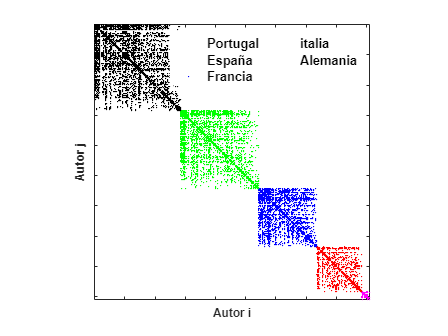

figure
tamanos_bloques = [size(Ale_Colab, 1), size(Ita_Colab, 1), size(Fra_Colab, 1), size(Esp_Colab, 1), size(Por_Colab, 1)];
limites_bloques = cumsum(tamanos_bloques);

spy(SM_Colab,'m');
hold on
spy(SM_Colab(1:limites_bloques(4),1:limites_bloques(4)),'r');
spy(SM_Colab(1:limites_bloques(3),1:limites_bloques(3)),'b');
spy(SM_Colab(1:limites_bloques(2),1:limites_bloques(2)),'g');
spy(SM_Colab(1:limites_bloques(1),1:limites_bloques(1)),'k');
axis([1 9088, 1 9088])
ylabel('Autor j','fontweight','bold')
xlabel('Autor i','fontweight','bold')
xticklabels(' ')
yticklabels(' ')
legend({'Portugal','España','Francia','italia','Alemania'},...
    'Location','northeast','NumColumns',2,'Box','off','FontWeight','bold','FontSize',12);
hold off

**Guardamos las matrices anteriores y la nueva supermatrix en un archivo .txt**

Solo descomentar si se quiere usar

% writematrix(SM_Colab,'SM_Colab','Delimiter',' ')
% writematrix(Fra_Colab,'Fra_Colab','Delimiter',' ')
% writematrix(Esp_Colab,'Esp_Colab','Delimiter',' ')
% writematrix(Ale_Colab,'Ale_Colab','Delimiter',' ')
% writematrix(Ita_Colab,'Ita_Colab','Delimiter',' ')
% writematrix(Por_Colab,'Por_Colab','Delimiter',' ')

### Guardamos algunas variables para usarlas en otros archivos de matlab

save("MatricesSparse.mat","Ale_Colab","Ita_Colab","Fra_Colab","Esp_Colab","Por_Colab",...
    "SM_Colab","Colab_diag_S","Colab_A_S","Colab_I_S","Colab_P_S","Colab_F_S","Colab_E_S","Colab_S")

#### Número exacto de conexiones en cada red

links_Ale = sum(sum(Ale_Colab))/2

links_Ale =    (1,1)          22159


links_Fra = sum(sum(Fra_Colab))/2

links_Fra =    (1,1)          13198


links_Ita = sum(sum(Ita_Colab))/2

links_Ita =    (1,1)          15720


links_Esp = sum(sum(Esp_Colab))/2

links_Esp =    (1,1)           8175


links_Por = sum(sum(Por_Colab))/2

links_Por =    (1,1)           1119


links = sum(sum(SM_Colab))/2

links =    (1,1)          60371
